# Quickstart: Accessing Two-Photon Calcium Imaging Data from the Allen Brain Observatory

This short example demonstrates the basics of exploring and examining items within the Visual Coding 2P dataset [1] from the Allen Brain Observatory [2].

### View and Filter Visual Coding 2P Dataset Items 

#### View Available Items

Use a `bot.list()` function to obtain a listing of all available experimental ***session*** items: 

availSessions = bot.listSessions('VisualCoding', 'Ophys'); % specify 'ophys' to indicate the Visual Coding 2P dataset

Similar functions exist for other dataset item types: `bot.listCells() & bot.listExperiments().`

The `bot.list()` functions return [**table** objects](https://www.mathworks.com/help/matlab/tables.html) containing identifiers and other columns of information about the available items: 

availSessions % simplified command equivalent to disp(availSessions)

availSessions = 2684×18 table
       id        experiment_container_id    mouse_id      session_type      targeted_structure_acronym    age_in_days    fail_eye_tracking    imaging_depth    sex                                     full_genotype                                         cre_line        date_of_acquisition                     name                     experiment_container     specimen     targeted_structure    well_known_files     dataset_name 
    _________    _______________________    _________    _______________    __________________________    ___________    ____

There are thousands of sessions in this dataset. The displayed table can be scrolled horizontally & vertically in the Live Editor to explore information about each. 

#### Filter Items by Criteria

Item tables can be filtered to focus on those meeting particular criteria of interest, by using [**tabular indexing**](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html) operations: 

% select experiments from the most orientation/direction-selective areas of visual cortex 
filteredSessions = availSessions(ismember(availSessions.targeted_structure_acronym, categorical(["VISal" "VISrl" "VISam"])), :);

% select experiments with GCaMP6f expression enriched in Layer 2/3 and Layer 4 of cortex
filteredSessions = filteredSessions(filteredSessions.cre_line == "Cux2-CreERT2", :);

% select experiments imaging from the shallowest depth in Layer 2/3
filteredSessions = filteredSessions(filteredSessions.imaging_depth == 175,:);

% select experiments with eye tracking data available
filteredSessions = filteredSessions(~filteredSessions.fail_eye_tracking, :);

% select experiments with drifting grating and natural movie stimuli
filteredSessions = filteredSessions(filteredSessions.session_type == "three_session_A", :);
disp(filteredSessions)

       id        experiment_container_id    mouse_id      session_type      targeted_structure_acronym    age_in_days    fail_eye_tracking    imaging_depth    sex                                     full_genotype                                        cre_line       date_of_acquisition                       name                      experiment_container     specimen     targeted_structure    well_known_files     dataset_name 
    _________    _______________________    _________    _______________    __________________________    ___________    _________________    

### Examine Session Items

#### Obtain Session of Interest

From the table of filtered items, one or more specific items can be obtained for further examination using the `bot.get() `functions`: `

sessionUnderStudy = bot.getSessions(filteredSessions(1,:)); 
sessionUnderStudy.info    

ans = struct with fields:
                            id: 503412730
       experiment_container_id: 511510695
                      mouse_id: 495727000
                  session_type: three_session_A
    targeted_structure_acronym: VISal
                   age_in_days: 143
             fail_eye_tracking: 0
                 imaging_depth: 175
                           sex: M
                 full_genotype: "Cux2-CreERT2/Cux2-CreERT2;Camk2a-tTA/wt;Ai93(TITL-GCaMP6f)/Ai93(TITL-GCaMP6f)"
                      cre_line: "Cux2-CreERT2"
           date_of_acquisition: 23-Feb-2016 19:10:20
                          name: "20160223_222425_3StimA"
          experiment_container: [1×1 struct]
                      specimen: [1×1 struct]
            targeted_structure: [1×1 struct]
              well_known_files: [3×1 struct]
                  dataset_name: "VisualCoding"


These `info` structure fields reflect the information from the session item's corresponding row in the filtered table above.

#### Examine Session of Interest

The session of interest can be examined more closely by displaying the obtained session item: 

disp(sessionUnderStudy)

  OphysSession (VisualCoding) with properties:

                                     id: 503412730
                                   info: [1×1 struct]
                           session_type: three_session_A
                            linkedFiles: [2×1 table]

   Linked Items
                             experiment: [1×1 bot.item.Experiment]
                                  cells: [119×94 table]

   Linked File Values ('SessNWB')
                      cell_specimen_ids: [517504202 587436644 517503508 517503561 587436632 587436622 517503501 517504212 517503135 517503347 517503344 517503416 517503412 517503338 587436443 517503511 517503305 517503515 517504434 … ] (1×119 int64)
          corrected_fluorescence_traces: '[on demand]'
                fluorescence_timestamps: '[on demand]'
                    fluorescence_traces: '[on demand]'
            fluorescence_traces_demixed: '[on demand]'
     

The displayed session item is an [**object**](https://www.mathworks.com/help/matlab/matlab_oop/create-a-simple-class.html) with has numerous additional [**properties**](https://www.mathworks.com/help/matlab/matlab_oop/create-a-simple-class.html#buoz2sc), allowing the session of interest to be examined more closely. 

### View and Plot Neural Activity in Detected Cells

For the Visual Coding 2P dataset, neural recordings were obtained from the visual cortex in the form of two-photon fluoresence. These are reflected in the varioius `fluorescence `properties: 

traces = sessionUnderStudy.fluorescence_traces_dff;
tall(traces) % display as a tall array 

ans =

  115744×119 tall single matrix

    0.1638    0.0245    0.1740    0.0660    0.0750    0.0769    0.1267    0.1671    0.1499    0.1691    0.2176    0.1915    0.0806    0.2626    0.1452    0.1646    0.0906    0.0778    0.1475    0.1540    0.2273    0.1097    0.0391    0.0863         0    0.1359    0.0338    0.2026    0.0495    0.1339    0.1579    0.1645    0.1676    0.1820    0.0568    0.0914    0.1277    0.1849         0    0.1441    0.1284    0.1596    0.1913    0.1472    0.1162    0.1407    0.1136    0.2652    0.1576    0.1689    0.1723    0.1736    0.1488    0.1374    0.2066    0.0838    0.1300    0.0827    0.0836    0.0724    0.0392    0.0915    0.1411    0.0766    0.2927    0.1136    0.0840    0.1449    0.1120    0.1266    0.1182    0.2791    0.1109    0.1046    0.2707    0.0736    0.1145    0.0069    0.0384    0.0439    0.0273    0.0815    0.0417    0.

Here the `fluorescence_traces_dff `property is displayed as a [**tall array**](https://www.mathworks.com/help/matlab/tall-arrays.html) making its contents easier to understand at a glance. It contains 100K+ rows (timepoints)  across a much smaller number (100+) of columns. The columns represent **cells **(putative neurons) which were detected by the originators of the Visual Coding 2P dataset. 

The corresponding timepoints are also provided in another session property: 

timestamps = sessionUnderStudy.fluorescence_timestamps;
size(timestamps)

ans =       115744           1


The number of timestamps equals the height of the fluorescence traces above.

With the timepoints and fluorescence traces from the computationally detected cells, a sampling of putative neural recordings can be plotted: 

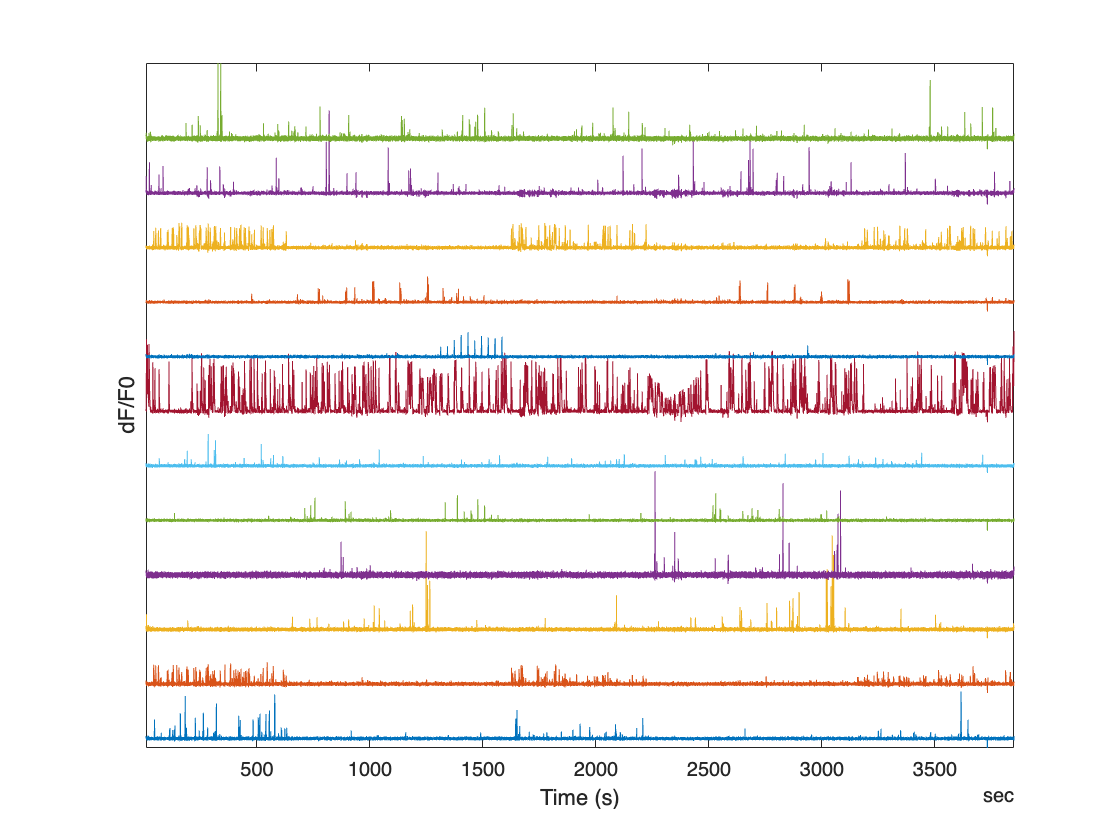

plot(timestamps, traces(:, 1:10:end) + (1:10:size(traces, 2))/3)
axis tight; xlabel('Time (s)'); set(gca, 'YTick', []); ylabel('dF/F0');

These putative cells differ considerably in the rates and patterns of peaks in their traces. This suggests there are a range of neural cell types and response types to the visual stimuli during the session. 

### Learn More

For an example of more in-depth neural data analysis of the Visual Coding 2P dataset using the Brain Observatory Toolbox, see the [**Ophys Demo**](matlab:open('./VisualCoding_OphysDemo.mlx')).

For more detailed guidance on how to use the Brain Observatory Toolbox with the Visual Coding 2P dataset, see the [**Ophys Tutorial**](matlab:open('./VisualCoding_OphysTutorial.mlx')).

### References

[1] Copyright 2016 Allen Institute for Brain Science. Visual Coding 2P dataset. Available from: [http://portal.brain-map.org/explore/circuits/visual-coding-2p](http://portal.brain-map.org/explore/circuits/visual-coding-2p).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 